clf
clear
plot_pdetection = 1;
plot_falsepositive = 0;
MAX_BIN = 20;
TOTAL_FRAMES = 1000;

base_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/csvs_to_plot/";
csvs = ["1GHzNoAttack.csv", "1GHzSimilarSlopeAndVelocity.csv"];
colors_list = ["b", "g", "c", "m", "y", "k", "r"];
color_idx = 1;

for csv = csvs
    table_data = readtable(base_path + csv);
    range_col = table_data{:, 1};
    bin_classification = cast(range_col/10, "int16")';
    histogram_vals = zeros(MAX_BIN,3);
    for bin_num = 1:MAX_BIN
        histogram_vals(bin_num, 1) = bin_num;
        count = 0;
        detected = 0;
        false_pos = 0;
        for frame = 1: TOTAL_FRAMES
            if (bin_classification(frame) == bin_num)
                count = count + 1;
                if table_data{frame, 3}
                    detected = detected + 1;
                end
                if table_data{frame, 8}
                    false_pos = false_pos + 1;
                end
            end
        end
        if (count ~= 0)
            histogram_vals(bin_num, 2) = detected/count;
            histogram_vals(bin_num, 3) = false_pos/count;
        end
    end

    if (plot_pdetection)
        hold on
        plot(histogram_vals(:,1)*10, histogram_vals(:,2), colors_list(color_idx));
        color_idx = color_idx +1;
        hold off
    end

    if (plot_falsepositive)
        hold on
        plot(histogram_vals(:,1)*10, histogram_vals(:,3), colors_list(color_idx));
        color_idx = color_idx + 1;
        hold off
    end
end

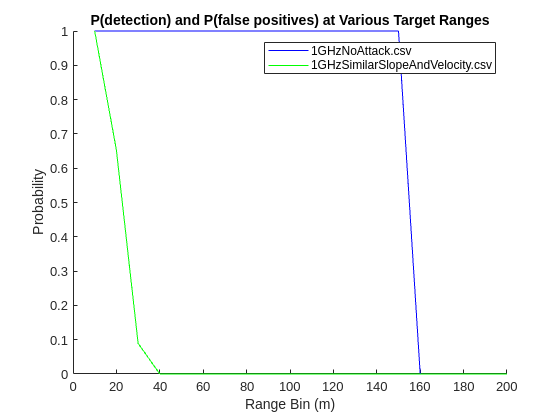

ylabel("Probability")
legend(csvs)
xlabel("Range Bin (m)")
title("P(detection) and P(false positives) at Various Target Ranges")